#### 3) An analog signal xc(t) = 5 cos(400π t) + 10 sin(500π t) is to be processed by a digital signal processor in which the sampling frequency is 1 kHz.

#### Design a minimum order FIR filter using one of the fixed windows that will pass the first component of xc(t) with attenuation of less than 1 dB but will attenuate the second component to at least 50 dB. Provide a filter response plot containing sub-plots of impulse, amplitude, log-magnitude, and error response plots.

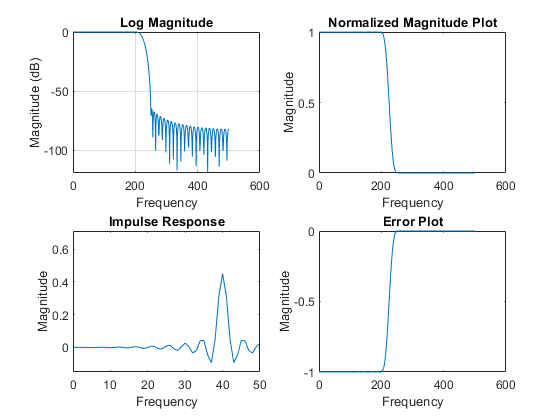

fs =  1000; % Sampling Frequency

t = 0:1/fs:1-1/fs; % Time Vector

xc1 = 5*cos(2*200*pi*t) ;
xc2 = 10*sin(2*250*pi*t); 
xc = xc1 + xc2; % Analog Signal

wp = 0.4; % digital Passband Normalized freq 
ws = 0.5; % digital Stopband Normalized freq 
Ap = 0.01; % Passband ripple in dB
As = 50; % Stopband attenuation in dB

% Filter Design
lpFilt = designfilt('lowpassfir','PassbandFrequency',wp, ...
         'StopbandFrequency',ws,'PassbandRipple',Ap, ...
         'StopbandAttenuation',As,'DesignMethod','kaiserwin');

% Frequency Response
[h,w] = freqz(lpFilt,[0:1:500],fs);
% Impulse Response
[i,w2] = impz(lpFilt,[0:1:500],fs);

hid = zeros(1,length(h));
e = abs(hid) - abs(h);

figure(1)

subplot(2,2,1)
plot(w,20*log10(abs(h)))
title("Log Magnitude")
ylabel('Magnitude (dB)')
xlabel('Frequency')
grid on;

subplot(2,2,2)
plot(w,abs(h));
ylabel('Magnitude')
xlabel('Frequency')
title('Normalized Magnitude Plot')

subplot(2,2,4)
plot(w,e)
title("Error Plot")
ylabel('Magnitude')
xlabel('Frequency')


subplot(2,2,3)
plot(w,i)
title("Impulse Response")
ylabel('Magnitude')
xlabel('Frequency')
xlim([0 50])
ylim([-0.15 0.71])

**BONUS QUESTION H.W 7-3**

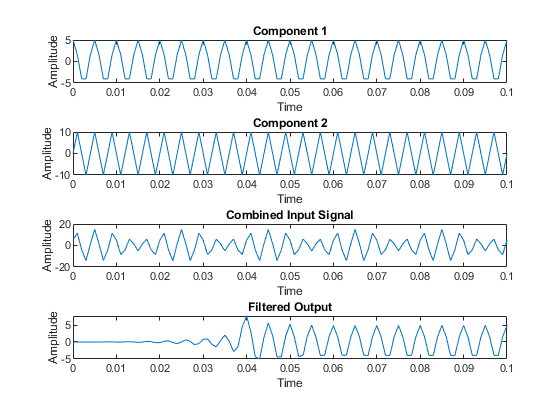

filteredData = filter(lpFilt,xc);

figure(2)

subplot(4,1,1)
plot(t,xc1)
title("Component 1")
ylabel('Amplitude')
xlabel('Time')
xlim([0 0.1])
ylim([-5.0 5.0])

subplot(4,1,2)
plot(t,xc2)
title("Component 2")
ylabel('Amplitude')
xlabel('Time')
xlim([0 0.1])

subplot(4,1,3)
plot(t,xc)
title("Combined Input Signal")
ylabel('Amplitude')
xlabel('Time')
xlim([0 0.1])

subplot(4,1,4)
plot(t,filteredData)
title("Filtered Output")
ylabel('Amplitude')
xlabel('Time')
xlim([0 0.1])

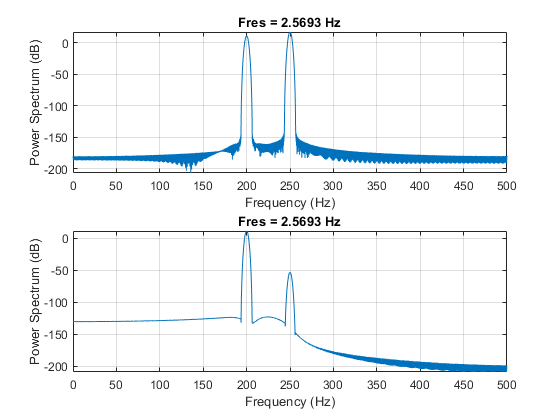

figure(3)
subplot(2,1,1)
pspectrum(xc,fs)
title("Power Spectrum Original")
subplot(2,1,2)
title("Power Spectrum Filtered Signal")
pspectrum(filteredData,fs)